clc; clearvars;

%% -------------------------
% Inputs
%% -------------------------
elev_angles_deg = 5:1:90;   % sweep from 5° to 90°
altitude_km     = 500;      % [km]
freq_mhz        = 437;      % [MHz]

% CubeSat TX
tx_pwr_Watt       = 1;      % [W]
tx_line_losses_dB = 1;      % [dB]
ant_gain_dBi      = 0;      % [dBi]

% Path / propagation losses
sat_pointing_loss_dB = 0;   % [dB]
polarization_loss_dB = 0;   % [dB]
atm_attenuation_dB   = 0;   % [dB]

% Ground Station RX
gs_ant_gain_dBi    = 15;    % [dBi]
gs_pointing_loss_dB= 0.5;   % [dB]
gs_line_loss_dB    = 1;     % [dB]
eff_noise_temp_K   = 300;   % [K]

% Data link
data_rate_bps    = 1000;    % [bps]
B_noise_Hz       = 20e3;    % [Hz]
EbN0_threshold_dB= 9.6;     % [dB] for BPSK

%% -------------------------
% Derived parameters
%% -------------------------
tx_pwr_dBW   = 10*log10(tx_pwr_Watt);
sat_EIRP_dBW = tx_pwr_dBW - tx_line_losses_dB + ant_gain_dBi;
Re_km = 6371; % Earth radius [km]

% Arrays for storage
range_km_arr = zeros(size(elev_angles_deg));
rec_power_dBW_arr = zeros(size(elev_angles_deg));
SNR_dB_arr = zeros(size(elev_angles_deg));
CNo_dBHz_arr = zeros(size(elev_angles_deg));
EbN0_dB_arr = zeros(size(elev_angles_deg));
link_margin_dB = zeros(size(elev_angles_deg));
free_space_loss_dB_arr = zeros(size(elev_angles_deg));
total_path_loss_dB_arr = zeros(size(elev_angles_deg));
N_dBW_arr = zeros(size(elev_angles_deg));

%% -------------------------
% Loop over elevation
%% -------------------------
for i = 1:length(elev_angles_deg)
    elev = elev_angles_deg(i);

    % Slant range (geometry-based)
    range_km = sqrt((Re_km + altitude_km)^2 - Re_km^2 * cosd(elev)^2) ...
               - Re_km * sind(elev);
    range_m = range_km * 1e3;
    range_km_arr(i) = range_km;

    % Free-space loss
    lambda_m = 3e8 / (freq_mhz*1e6);
    free_space_loss_dB = 20*log10(4*pi*range_m / lambda_m);
    free_space_loss_dB_arr(i) = free_space_loss_dB;

    % Total path loss
    total_path_loss_dB = free_space_loss_dB + sat_pointing_loss_dB + ...
                         polarization_loss_dB + atm_attenuation_dB;
    total_path_loss_dB_arr(i) = total_path_loss_dB;

    % Received power
    rec_power_dBW = sat_EIRP_dBW - total_path_loss_dB + gs_ant_gain_dBi ...
                    - gs_pointing_loss_dB - gs_line_loss_dB;
    rec_power_dBW_arr(i) = rec_power_dBW;

    % Noise power
    k = 1.380649e-23;
    N_W = k * eff_noise_temp_K * B_noise_Hz;
    N_dBW = 10*log10(N_W);
    N_dBW_arr(i) = N_dBW;

    % SNR
    SNR_dB_arr(i) = rec_power_dBW - N_dBW;

    % C/N0
    G_rx_eff_dBi = gs_ant_gain_dBi - gs_pointing_loss_dB - gs_line_loss_dB;
    gs_figure_of_merit = G_rx_eff_dBi - 10*log10(eff_noise_temp_K);
    CNo_dBHz = sat_EIRP_dBW - total_path_loss_dB + gs_figure_of_merit + 228.6;
    CNo_dBHz_arr(i) = CNo_dBHz;

    % Eb/N0
    EbN0_dB = CNo_dBHz - 10*log10(data_rate_bps);
    EbN0_dB_arr(i) = EbN0_dB;

    % Link margin
    link_margin_dB(i) = EbN0_dB - EbN0_threshold_dB;
end

%% -------------------------
% Results table
%% -------------------------
results_table = table(elev_angles_deg', range_km_arr', free_space_loss_dB_arr', ...
    total_path_loss_dB_arr', rec_power_dBW_arr', N_dBW_arr', SNR_dB_arr', ...
    CNo_dBHz_arr', EbN0_dB_arr', link_margin_dB', ...
    'VariableNames', {'Elevation_deg','SlantRange_km','FSPL_dB','TotalLoss_dB', ...
    'RecPower_dBW','NoisePower_dBW','SNR_dB','CNo_dBHz','EbN0_dB','LinkMargin_dB'});

disp(results_table)

    Elevation_deg    SlantRange_km    FSPL_dB    TotalLoss_dB    RecPower_dBW    NoisePower_dBW    SNR_dB    CNo_dBHz    EbN0_dB    LinkMargin_dB
    _____________    _____________    _______    ____________    ____________    ______________    ______    ________    _______    _____________

          5             2077.1         151.6         151.6          -139.1          -160.82        21.717     64.728     34.728        25.128    
          6               1992        151.24        151.24         -138.74          -160.82        22.081     65.092     35.092        25.492    
          7             1911.3        150.88        150.88         -138.38 

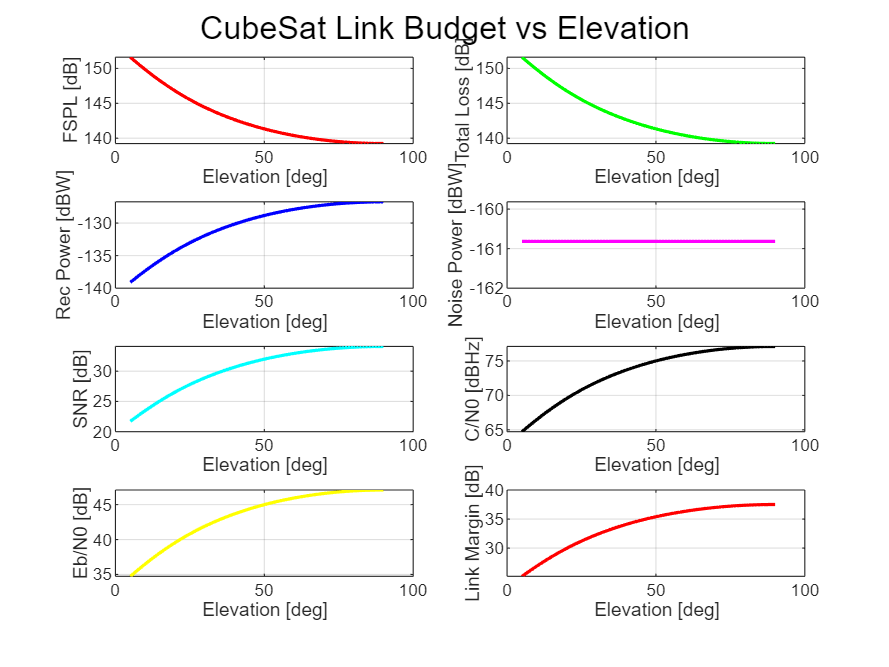


%% -------------------------
% Plots
%% -------------------------
figure;

subplot(4,2,1)
plot(elev_angles_deg, free_space_loss_dB_arr,'r','LineWidth',1.5);
xlabel('Elevation [deg]'); ylabel('FSPL [dB]'); grid on;

subplot(4,2,2)
plot(elev_angles_deg, total_path_loss_dB_arr,'g','LineWidth',1.5);
xlabel('Elevation [deg]'); ylabel('Total Loss [dB]'); grid on;

subplot(4,2,3)
plot(elev_angles_deg, rec_power_dBW_arr,'b','LineWidth',1.5);
xlabel('Elevation [deg]'); ylabel('Rec Power [dBW]'); grid on;

subplot(4,2,4)
plot(elev_angles_deg, N_dBW_arr,'m','LineWidth',1.5);
xlabel('Elevation [deg]'); ylabel('Noise Power [dBW]'); grid on;

subplot(4,2,5)
plot(elev_angles_deg, SNR_dB_arr,'c','LineWidth',1.5);
xlabel('Elevation [deg]'); ylabel('SNR [dB]'); grid on;

subplot(4,2,6)
plot(elev_angles_deg, CNo_dBHz_arr,'k','LineWidth',1.5);
xlabel('Elevation [deg]'); ylabel('C/N0 [dBHz]'); grid on;

subplot(4,2,7)
plot(elev_angles_deg, EbN0_dB_arr,'y','LineWidth',1.5);
xlabel('Elevation [deg]'); ylabel('Eb/N0 [dB]'); grid on;

subplot(4,2,8)
plot(elev_angles_deg, link_margin_dB,'r','LineWidth',1.5);
xlabel('Elevation [deg]'); ylabel('Link Margin [dB]'); grid on;

sgtitle('CubeSat Link Budget vs Elevation');